**Section 2.1.1**

I used the symbolic tooblbox to carry out the inverse transform method

M = [10, 10^2, 10^3, 10^4, 10^5, 10^6]; a = 0; b = 1;
rng(0); 

**1) Exponential Distribution**

%Exponential Distribution - Inverse Transfrom Method
lambda = 9; 
syms x 
f_x = lambda*exp(-lambda*x); %pdf - theory
u = int(f_x, [0, x]); %cdf, u = F(x)
f_inv = finverse(u); %F^-1

f_inv = matlabFunction(f_inv); 
f_x = matlabFunction(f_x); 

Theoretical 

%Exponential Distribution - Theory  
y = f_x(0:0.01:1);

Plot - vary the number of samples

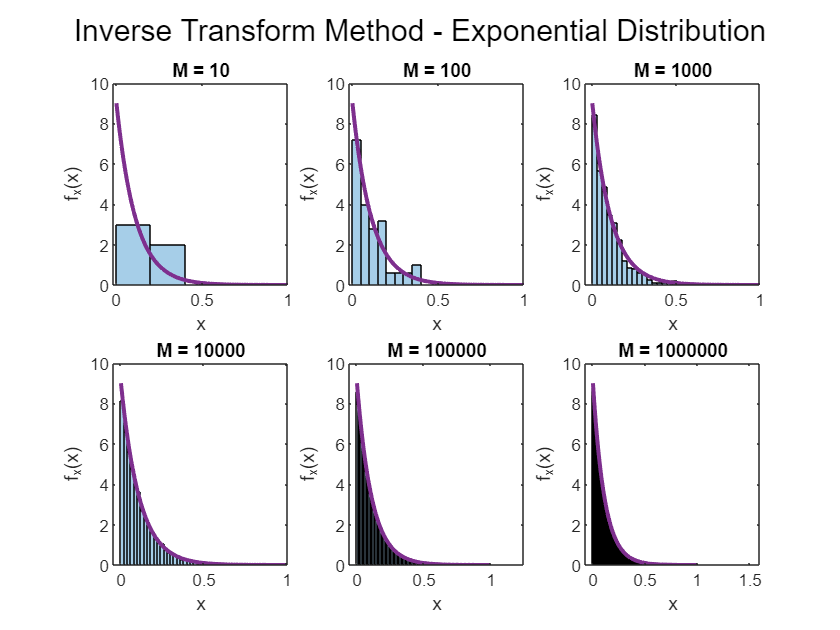

figure
for i = 1:length(M)
    Legend = cell(2,1); 
    U = a + (b-a).*rand(M(i), 1); 
    X = f_inv(U); %F^-1(U)
    subplot(2,3,i)
    histogram(X, 'FaceAlpha', 0.35, 'Normalization','pdf')
    hold on
    plot(0:0.01:1,y, 'LineWidth', 2, 'Color', "#7E2F8E")
    xlabel('x')
    ylabel('f_{x}(x)')
    title(sprintf('M = %d', M(i)))
end 
sgtitle('Inverse Transform Method - Exponential Distribution')
hold off

**A: The quality of the results improves as the number of samples improves. The inverse transform method begins to match theory around the M=10^3 samples. **

**2) Rayleigh Distribution**

alpha = 14;
f_x = (x/alpha^2)*exp(-(x^2/(2*alpha^2))); %pdf - theory
u = int(f_x, [0, x]); %cdf, u = F(x)
f_inv = finverse(u); %F^-1

f_inv = matlabFunction(f_inv); 
f_x = matlabFunction(f_x);

Theoretical

%Rayleigh Distribution - Theory  
y = f_x(0:0.01:50);

Plot - Vary the number of samples

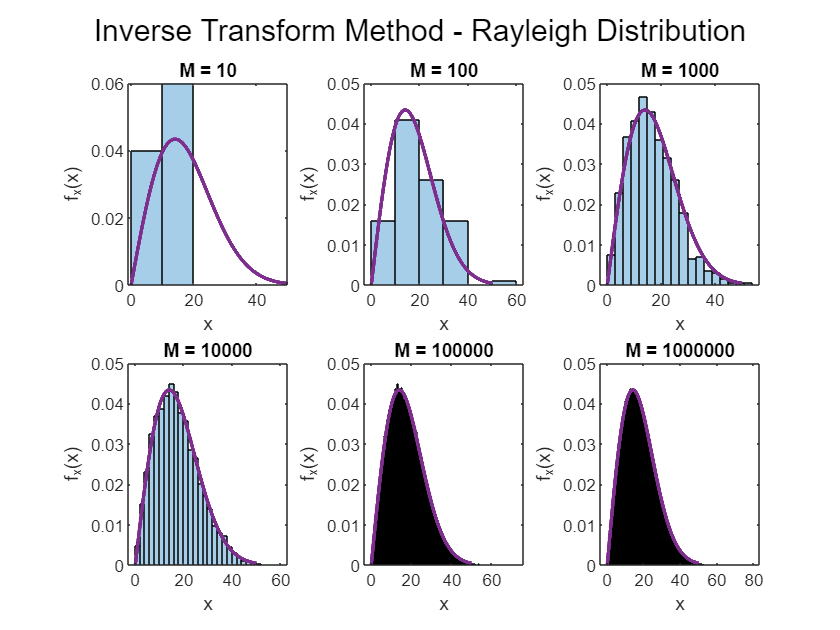

figure
for i = 1:length(M)
    U = a + (b-a).*rand(M(i), 1); 
    X = f_inv(U); %F^-1(U)
    subplot(2,3,i)
    histogram(X, 'FaceAlpha', 0.35, 'Normalization','pdf')
    hold on
    plot(0:0.01:50,y, 'LineWidth', 2, 'Color', "#7E2F8E")
    xlabel('x')
    ylabel('f_{x}(x)')
    title(sprintf('M = %d', M(i)))
end 
sgtitle('Inverse Transform Method - Rayleigh Distribution')
hold off

**A: The quality of the results improves as the number of samples improves. The inverse transform method begins to match theory around the M=10^3 mark, and matches theory at M=10^4. **

**3) Cauchy Distribution -- I had difficulty getting this to work**

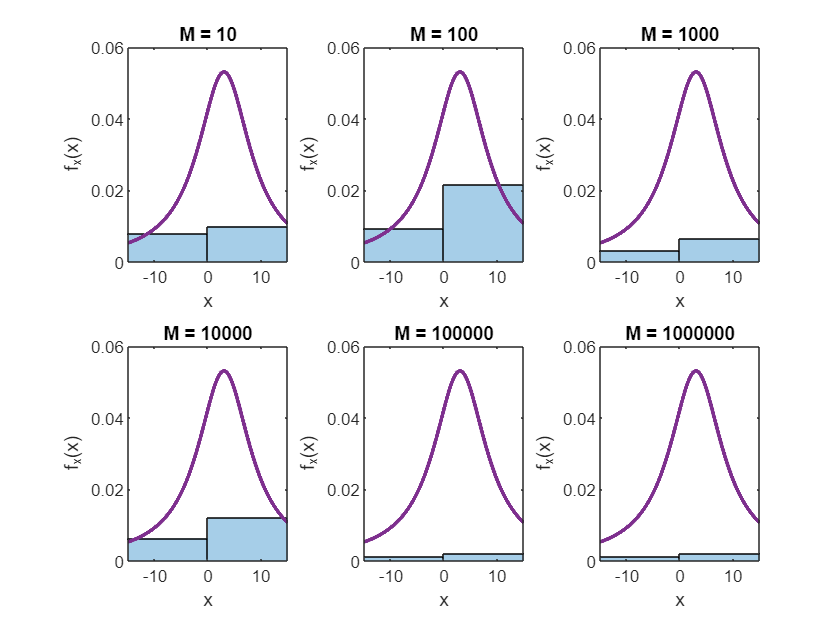

y = -15:0.01:15; 
f_x = @(x) (6/pi)./(6^2+(x-3).^2); 
f_inv = @(x) 6*tan(pi.*x-atan(1/2))+3; 
figure
for i = 1:length(M)
    U = a + (b-a).*rand(M(i), 1); 
    X = f_inv(U); 
    subplot(2,3,i)
    histogram(X, 'FaceAlpha', 0.35, 'Normalization','pdf') 
    hold on
    plot(y, f_x(y), 'LineWidth', 2, 'Color', "#7E2F8E")
    xlabel('x')
    xlim([-15,15])
    ylabel('f_{x}(x)')
    title(sprintf('M = %d', M(i)))
end 

hold off

**Section 2.1.2 - Discrete Distributions**

Run first

M = [10, 10^2, 10^3, 10^4, 10^5, 10^6]; a = 0; b = 1;
rng(0); 

**1) Bernoulli Distribution - Note I don't know why the title looks like that**

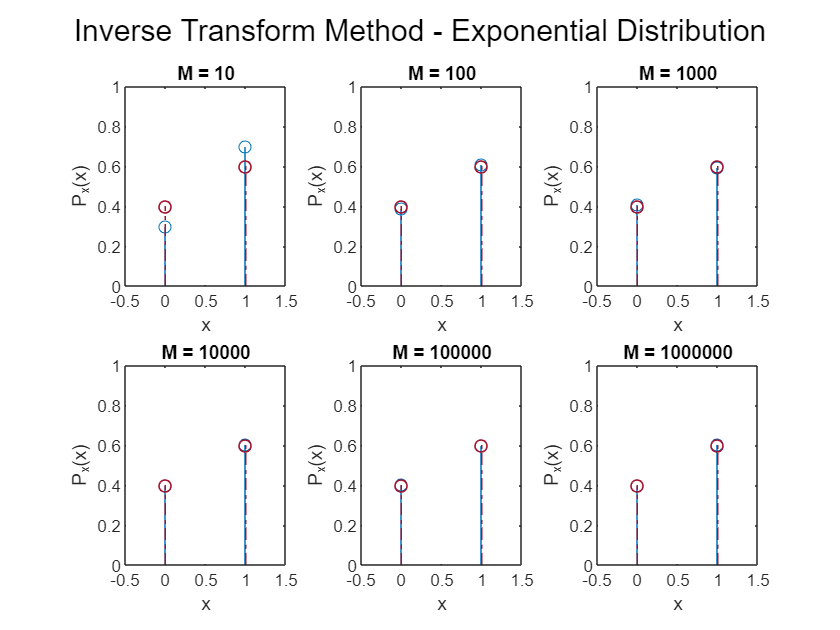

p = 0.4; 
X = [0, 1]; 

figure
for i = 1:length(M)
    U = a + (b-a).*rand(M(i), 1); 
    U(U >= p) = 1;
    U(U<p) = 0;
    one = length(find(U==1)); %find # of times 1 appears 
    zero = M(i) - one; %find # of times 0 appears 
    probs = [zero/M(i), one/M(i)]; 
    subplot(2,3,i)
    stem(X, probs)
    hold on
    stem(X, [0.4, 0.6], 'LineWidth', 0.8, 'Color', 	"#A2142F", 'LineStyle',"-.") %theory
    xlabel('x')
    xlim([-0.5 1.5])
    ylim([0 1])
    ylabel('P_{x}(x)')
    title(sprintf('M = %d', M(i)))
end 
hold off

**The sampling method improves when more samples are used. After 100 samples, the sampling method (blue) matches the discrete distribution (orange). **

**2) Binomial Distribution - *****this runs for a while if M = 10^6 so I only ran the code for up to 10^4***

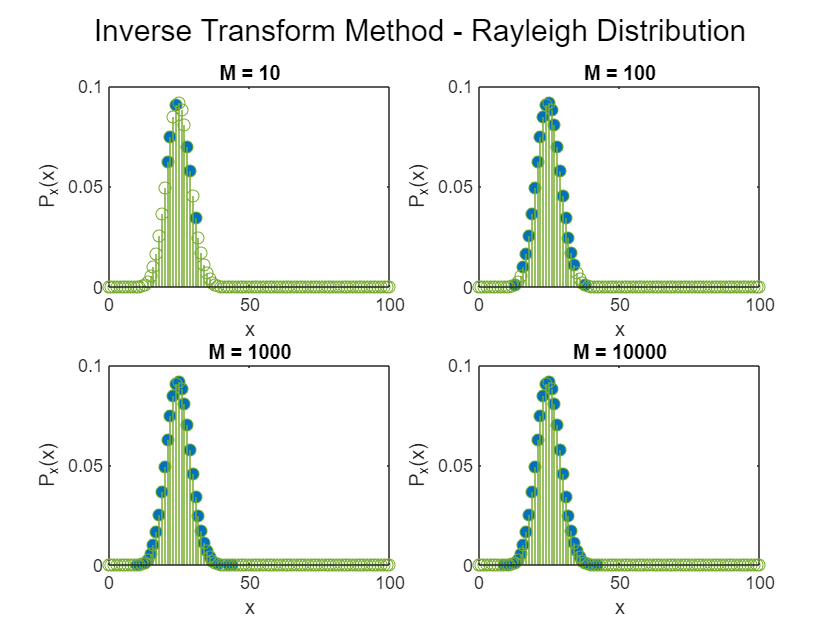

running M = 10
running M = 100
running M = 1000
running M = 10000


warning('off','all'); %suppress warnings about coefficient
n = 100; p = 0.25; q = 1-p; 
y = binopdf(0:100,100,0.25);

figure
for i = 1:4
    fprintf('running M = %d\n', M(i))
    X = zeros(1, M(i)); 
    p_k = zeros(1, M(i));
    %repeat 100 trials M times
    for j=1:M(i) 
        u = a + (b-a).*rand(n, 1); 
        u(u>p) = 0; 
        u(u<=1-p & u~=0) = 1; %don't want to set 0s to 1s
        k = sum(u); %number of successes for 100 trials
        X(j) = k; %determine k 
        c = nchoosek(n, k); %combinatorics
        p_k(j) = c*p^k*q^(n-k); %calculate probability
    end
    %plot
    subplot(2,2,i)
    stem(X,p_k, 'Filled')
    hold on
    stem(0:100,y, 'Color', '#77AC30')
    xlabel('x')
    %xlim([-0.5 1.5])
    %ylim([0 1])
    ylabel('P_{x}(x)')
    title(sprintf('M = %d', M(i)))
    hold off
end 

**The sampling method (blue circles) begins to look like the binomial distribution (red) after 1000 samples.  More samples results in a better estimation. **

**3) Geometric Distribution**

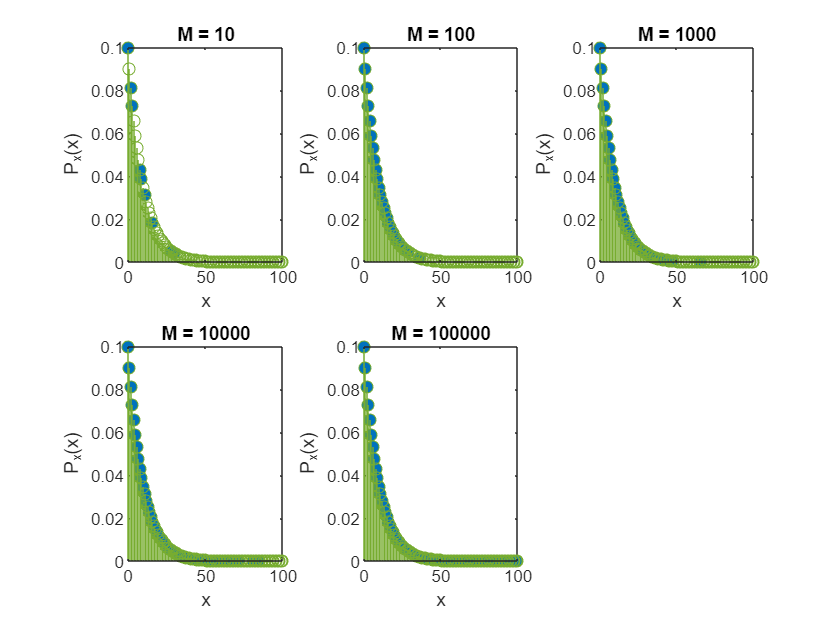

running M = 10
running M = 100
running M = 1000
running M = 10000
running M = 100000


warning('off', 'all') %supress warnings about coefficents
p = 0.1; q = 1-p; n = 100; 
x = 0:100;
y = geopdf(x,0.1);

figure
for i=1:5
    fprintf('running M = %d\n', M(i))
    X = zeros(1, M(i)); 
    p_k = zeros(1, M(i));
    for j = 1:M(i)
        u = a + (b-a).*rand(n, 1); 
        u(u>p) = 0; 
        u(u<=q & u~=0) = 1; %don't want to set 0s to 1s
        idx = find(u,1)-1;
        if isempty(idx)
            %in case of no succesful trials
            X(j) = 100;
            p_k(j) = p*q^100;
        else 
            X(j) = idx;  %find first success
            p_k(j) = p*q^X(j); %calc probability
        end
    end 
subplot(2,3,i)
stem(X, p_k,'filled'); 
hold on 
stem(x,y,"Color","#77AC30")
xlabel('x')
ylabel('P_{x}(x)')
title(sprintf('M = %d', M(i)))
hold off
end 

**The sampling method (blue circles) begins to look like the geometric distribution (green) after 1000 samples.  More samples results in a better estimation.**

**4) Poisson Distribution**

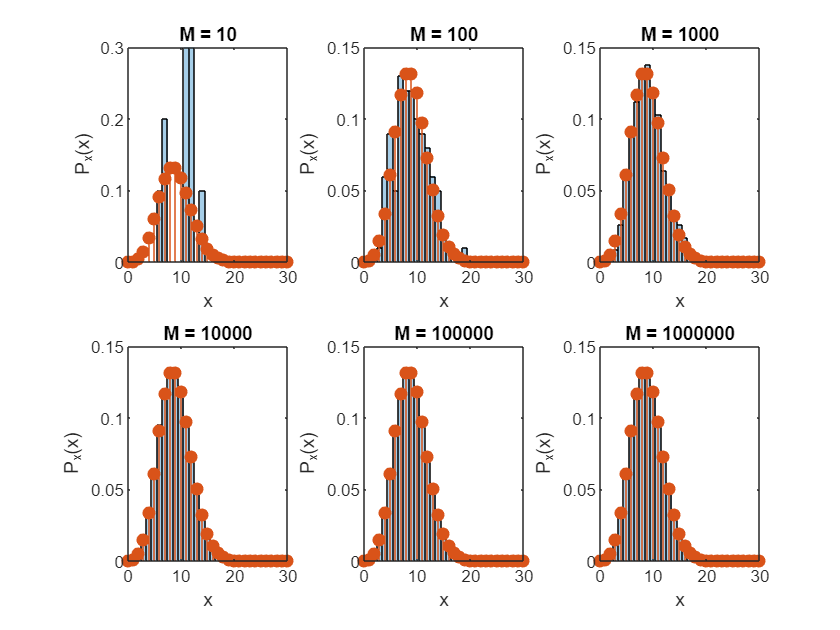

lambda = 9;
f_inv = @(x) -log(1-x)/9;
y = poisspdf(0:100, lambda); %theory
figure; 
for i = 1:length(M)
    X = zeros(1, M(i));
   for j = 1:M(i)
        x = 0; 
        SUM = 0; 
        while 1
              u = a + (b-a).*rand; 
              val = f_inv(u); 
              SUM = SUM + val; 
              if SUM <=1
                  x=x+1; 
              else
                  break
              end 
        end 
        X(j) = x; %observations
   end
    subplot(2,3,i)
    histogram(X, 'Normalization', 'probability', 'FaceAlpha', 0.35)
    hold on 
    stem(0:100, y, 'Filled'); 
    xlim([0 30])
    xlabel('x')
    ylabel('P_{x}(x)')
    title(sprintf('M = %d', M(i)))
    hold off
end 

**The sampling method (blue bars) begins to look like the poisson distribution (orange) after 1000 samples.  More samples results in a better estimation.**

**Section 2.2 - Accept Reject Method**

A) Show that $c \geq 1$


$$\int_{-\infty}^{x}f_{target}(u)du \leq c\cdot\int_{-\infty}^{x}f_{proposal}(u)du \\
F_{target}(x) \leq c \cdot F_{proposal}(x) \\
\int_{-\infty}^{\infty}F_{target}(x)dx\leq c\cdot\int_{-\infty}^{\infty}F_{proposal}(x)dx \\
\therefore 1 \leq c
$$


B) Compute the acceptance probability given X=x


$$P(U\leq f_{target}(x) | X=x) = \frac{f_{target}(x)}{c\cdot f_{proposal}(x)}$$


C) Compute the probability the acceptance probability:


$$P(\text{X is accepted}) = \int_{-\infty}^{\infty} P(U\leq f_{target}(x)) f_{proposal}(x) dx\\
=\int_{-\infty}^{\infty}\frac{f_{target}(x)}{c\cdot f_{proposal}}\cdot f_{proposal}(x)\\
=\frac{1}{c}\int_{-\infty}^{\infty} f_{target}(x)dx
=\frac{1}{c}$$


D) Show that for all a, $P(X\leq a | U \leq f_{target}(x)) = F_{target}(a)$


$$P(X\leq a | U \leq f_{target}(x)) = \frac{P(U \leq f_{target}(x) | X \leq a)P(X \leq a)}{P(U \leq f_{target}(x)} \\
= \frac{\frac{F_{target}(a)}{c\cdot F_{proposal}(a)}\cdot F_{proposal}(a)}{\frac{1}{c}} = F_{target}(a)$$


E) Let N denote the number of repitions until a sample is accepted, compute E[N]

N would be a geometric r.v. ie: $$P(N=n) = (1-p)^{n-1}p, n\geq 1$$

$E[P(N=n)] = \frac{1}{p}$ and if $P(\text{acceptance}) = \frac{1}{c}$ then $E[P(N=n)] = c$

F) 


$$\min_{\lambda} E[N] = \min_{\lambda} c = \min_{\lambda} \frac{0.5x^2e^{-x}}{\lambda e^{-\lambda x}} = 0.5x^2 \frac{d}{d\lambda} \big(\frac{ e^{(\lambda -1)x}}{\lambda}\big)$$



$$\frac{d}{d\lambda} \big(\frac{ e^{(\lambda -1)x}}{\lambda}\big) = 0 \\
\frac{d}{d\lambda} \big(\frac{ e^{(\lambda -1)x}}{\lambda}\big) = \frac{e^{x(\lambda -1)}x}{\lambda} - \frac{e^{x(\lambda -1)}}{\lambda ^2} = 0 \\
\rightarrow \lambda e^{x(\lambda -1)} x = e^{x (\lambda -1)} \\
\rightarrow \lambda x =1 \\
\lambda = \frac{1}{x}
$$


Letting x = 1 yields $\lambda = 1$ and c = 1/2 therefore $E[N] = \frac{1}{2}$

x_proposal = @() 10*rand; c=3; %we will sample from uniform from 0 to 10, don't want pdf value
f_proposal = @(x) unifpdf(x,0,10); %this will return the pdf f(x)
f_target = @(x) normpdf(x, 4, sqrt(2)); %this will return pdf, need to pass x_proposal

num_samples = 1e4; %N
X=zeros(num_samples,1); %preallocate

Plot the target vs. proposal distribution

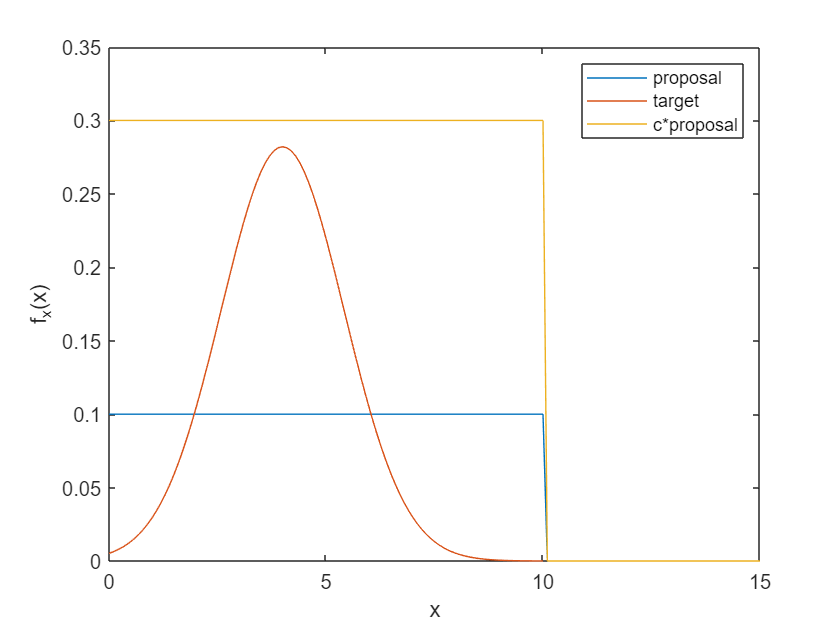

figure
plot(0:0.1:15, f_proposal(0:0.1:15))
hold on
plot(0:0.1:10, f_target(0:0.1:10)); 
hold on
plot(0:0.1:15, c*f_proposal(0:0.1:15)); 
xlabel('x')
ylabel('f_{x}(x)')
legend('proposal','target','c*proposal')

I chose the uniform distribution as the proposal distribution to sample from since I could ensure that the traget distribution fell within the area of proposal distribution, see the yellow and orange plots above. 

**Do accept reject method**

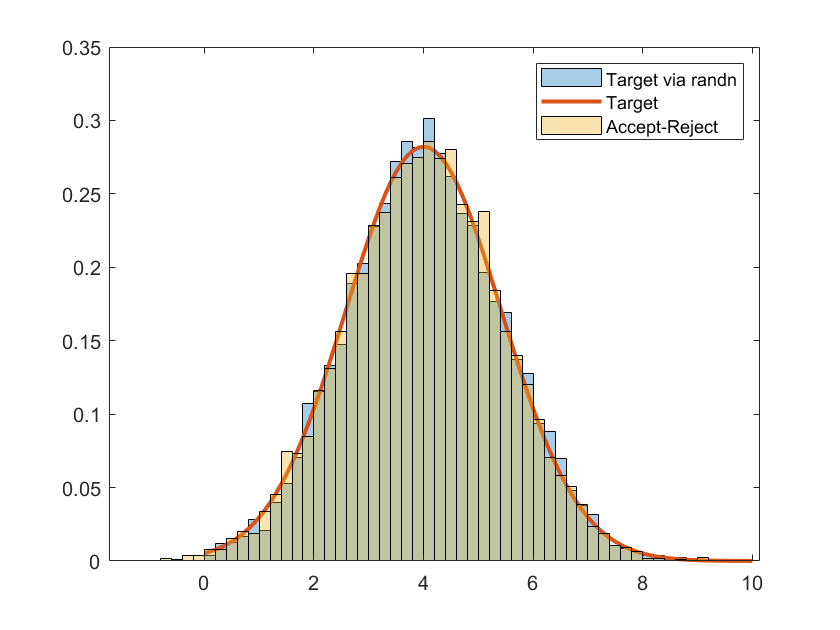

for i = 1:num_samples
    accept = 0; 
    while accept == 0
        v = x_proposal();  %sample propsal distribution for an observation, X=x
        u = (c*f_proposal(v))*rand(); %genearte over the range [0,cfproposal(x)] 
        if u <= f_target(v)
            accept = 1; %accept sample
            %disp('accepted sample')
            X(i) = v;  %save sample
        end
    end
end 
figure 
theory = normpdf(0:0.1:10, 4, sqrt(2)); 
theory_randn = sqrt(2)*randn(1e4,1)+4; 
histogram(X, 'Normalization', 'pdf', 'FaceAlpha', 0.35)
hold on
plot(0:0.1:10,theory, 'LineWidth', 2)
hold on 
histogram(theory_randn, 'Normalization', 'pdf', 'FaceAlpha', 0.35)
legend('Target via randn', 'Target', 'Accept-Reject')

The plot shows that the accept reject method yields similar results to the randn function, with some differnece at the peak of the distribution. Although the quality of these results are acceptable, the speed of the method could be improved by using a propsal distribution that closely matched the target distribution. That is the area between the proposal distribution and the target distribution is minimal, therefore we reject less samples which improves the speed of the algorithm. Of course, using more samples will also improve the result. 

**Section 3 - Whitening and Color Transformation for Gaussian Random Vectors**

1a-c

A = [3/2, 1/2; 1/2, 3/2]; %covariance matrix
Z = randn(1e3,2); %generate N iid samples, z_i
X = A*Z'; %transformed N samples, x_i

1d: estimate the mean of the transformed vector

u_x = mean(X, 2)

u_x =    -0.0645
   -0.0717


1e: estimate the auto-covariance matrix

sum= 0; 
for i = 1:length(X)
    sum = sum + (X(:,i)*X(:,i).'); 
end 
sigma_xx = sum/length(X) - (u_x*u_x')

sigma_xx =     2.5813    1.6080
    1.6080    2.6328


1f: Determine the empircal joint densities 

Becuase z1 and z2 are iid gaussian their correlation is zero, the variance is 1, and the mean is zero, so the joint density evaluates to be the following:


$$f_{Z_1Z_2}(z_1, z_2)=\frac{1}{2\pi}e^{-\frac{1}{2}[z_1^2+z_2^2]$$


The mean for x1 and x2 were calcualted to be 0.0711 and 0.06, respectively. The variances are $\sigma_{x_1} = 2.5288 \,\,\,\,\sigma_{x_2} = 2.4883$. The corrleation is $$\rho_{x_1x_2}=\frac{1.5146}{\sqrt{\sigma_{x_1}\sigma_{x_2}}} = 0.604$$. Therefore, the joint density for x1 and x2 is the following:


$$f_{X_1}{X_2}(x_1, x_2) = \frac{1}{2\pi\cdot2.5288\cdot2.4883\cdot\sqrt{1-0.604^2}}exp\bigg\{ \frac{-1}{2\cdot(1-0.604^2)}\bigg[\Big(\frac{x_1-0.0711}{2.5288}\Big) - 2\cdot0.604\cdot\Big(\frac{x_1-0.0711}{2.5288}\Big)\cdot\Big(\frac{x_2-0.06}{2.4883}\Big)+\Big(\frac{x_2-0.06}{2.4883}\Big)
\bigg]\bigg\}$$


*Note: values might not be the same if this script was re-run.  *

**From the above, we can say that the transformation, A, has correlated the random variables Z1 and Z2. **

1g-h: What are the covariance forms for each of the above correlation coefficients? 


$$COV(X,Y) = \rho_{x,y}\sqrt{\sigma_x\cdot\sigma_y}$$


p = [0.1, 0.5, 0.8, 1]; %correlation that we want
cov = p.*(sqrt(sigma_xx(1,1)*sigma_xx(2,2))); %covariance from above
 
for j = 1:length(p)
    fprintf('covariance form for pxy = %0.1f\n', p(j));
    disp([sigma_xx(1,1), cov(j); cov(j), sigma_xx(2,2)])
end 

covariance form for pxy = 0.1


    2.5813    0.2607
    0.2607    2.6328



covariance form for pxy = 0.5


    2.5813    1.3035
    1.3035    2.6328



covariance form for pxy = 0.8


    2.5813    2.0855
    2.0855    2.6328



covariance form for pxy = 1.0


    2.5813    2.6069
    2.6069    2.6328



2a-b: 

sigma_test = [5/2, 3/2; 3/2, 5/2]; 
R = sec3part2(sigma_test); 

%check function works by calculating autocovariance
u_test = mean(R, 2)

u_test =     0.0029
   -0.0012


sum= 0; 
for i = 1:length(R)
    sum = sum + (R(:,i)*R(:,i).'); 
end 
sigma_test = sum/length(R) - (u_test*u_test')

sigma_test =     2.4998    1.4880
    1.4880    2.4787


Looking at sigma_test we can see that the variance for the vectors in R are ~5/2, and the covariance ~3/2. This verifies the function works. 

2.c: How would the covariance of X change if Z was zero mean, unit variance, iid uniform random varaibles? 

%generate Z to be iid uniform r.v.
Z = sqrt(3)*(2*rand(1e7, 2)-1); %generates 2 uniform r.v. with 1,000 samples 
u_z = mean(Z) %check this is ~0

u_z = 	1.0e+-3 *

    0.5910    0.0441


Z = Z'; 
sum= 0; 
for i = 1:length(Z)
    sum = sum + (Z(:,i)*Z(:,i).'); 
end 
sigma_zz= sum/length(Z) - (u_z*u_z') %check sigma_zz = ~I; 

sigma_zz =     1.0000   -0.0005
   -0.0005    0.9998


%assume A remains the same from part 1c
X = A*Z; 
u_x = mean(X, 2)

u_x = 	1.0e+-3 *

    0.9085
    0.3616


sum= 0; 
for i = 1:length(X)
    sum = sum + (X(:,i)*X(:,i).'); 
end 
sigma_xx = sum/length(X) - (u_x*u_x')

sigma_xx =     2.4992    1.4987
    1.4987    2.4988


The result of applying a transformation to a vector of iid uniform rv with unit variance and zero mean are a set of random variables that no longer have unit variance and zero mean, but are identically distributed uniform random variables. So applying the transformation correlated the random variables in Z. 

function R = sec3part2(V)
%V is covariance matrix
   %check if covariance matrix is valid
    if (~issymmetric(V) || ~all(eig(V)>=0))
        error('invalid matrix structure')
    end 
    mu = zeros(1,length(V)); % assuming zero mean
    R = mvnrnd(mu, V, 1e5); %return vectors that obey V
    R = R';
end 